Load data.

clear
load('PowerChargerDataTable.mat')

Plot power usage in traditional charging station.

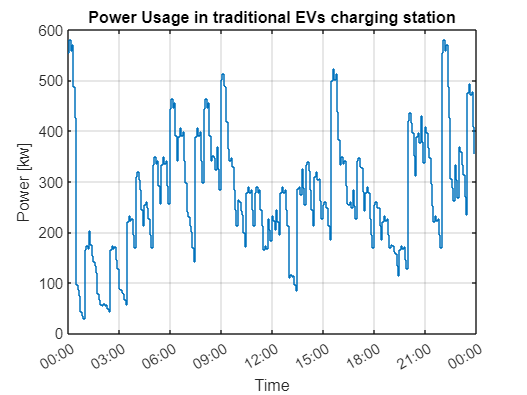

time = ChargerData.timestamp;
totalPower = ChargerData.ChargerPower.TotalkWhs;
totalPower = totalPower*(60*60); % convert kWh/s to kW
stairs(time, totalPower)
title('Power Usage in traditional EVs charging station')
datetick('x','HH:MM')
xlabel('Time')
ylabel('Power [kw]')
grid on

Set threshold value to start charge or discharge ESS.

pChgEss = 400;      % Start charging ESS after power usage drop below this value [kW]
pDscEss = 500;      % Start discharge ESS after power usage above this value [kW]

Set Energy capacity [Kwh] and E-rate for ESS. (assume charge and discharge rate is equal)

capa = 100;
Erate = 1;

Set initail and limit SoC of Ess.

soc = 0.7;
soc_min = 0.1;
soc_max = 0.9;

Set on/off peak time.

onPeakStr  = datetime(2023,11,9,9,0,0);     % on-peak time start from 9.00
offPeakStr = datetime(2023,11,9,22,0,0);    % off-peak time start from 22.00

Determine time step (dt) in seconds.

dt = [time; time(1)] - [time(1); time];
dt = dt(2:end-1);
dt = seconds(mean(dt));

ESS algorithm.

Pev = totalPower';
Pbatt = zeros(1,length(time));
Ebatt = zeros(1,length(time)+1);
Ebatt(1) = capa * soc;
Ebatt_min = capa * soc_min;
Ebatt_max = capa * soc_max;

for i = 1:length(time)
    if Pev(i) < pChgEss
        % charge
        Echg = -capa*Erate*(dt/3600);   % ESS using active sign convension
        if (Ebatt(i)-Echg) > Ebatt_max  % battery is full ?
            Pbatt(i) = 0;
            Echg = 0;
        else
            if (onPeakStr < time(i)) && (time(i) < offPeakStr) % on-peak period
                Pbatt(i) = 0;
                Echg = 0;
            else
                Pbatt(i) = -capa*Erate;
            end
        end
        
        Ebatt(i+1) = Ebatt(i) - Echg;

    elseif Pev(i) > pDscEss
        % discharge
        Edsc = capa*Erate*(dt/3600);
        if (Ebatt(i)-Edsc) < Ebatt_min  % battery is deplete ?
            Pbatt(i) = 0;
            Edsc = 0;
        else
            Pbatt(i) = capa*Erate;
        end
        
        Ebatt(i+1) = Ebatt(i) - Edsc;
    else
        Ebatt(i+1) = Ebatt(i);
    end
end

Pgrid = Pev - Pbatt;

Plot grid power.

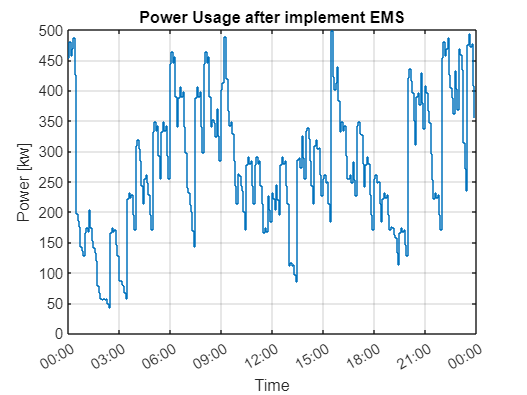

stairs(time, Pgrid)
title('Power Usage after implement EMS')
datetick('x','HH:MM')
xlabel('Time')
ylabel('Power [kw]')
grid on

Plot ESS energy.

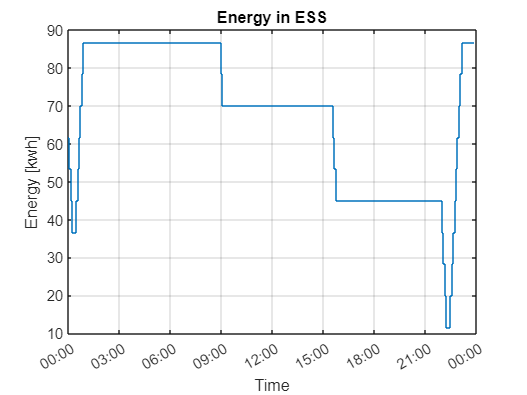

stairs(time, Ebatt(2:end))
title('Energy in ESS')
datetick('x','HH:MM')
xlabel('Time')
ylabel('Energy [kwh]')
grid on

Plot ESS power.

% stairs(time, Pbatt)
% title('ESS State of Energy')
% datetick('x','HH:MM')
% xlabel('Time')
% ylabel('Battery Power[kW]')
% grid on

Compare grid power.

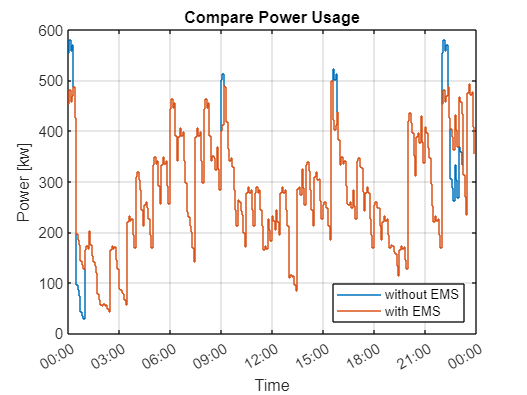

stairs(time, Pev)
hold on
stairs(time, Pgrid)
legend('without EMS', 'with EMS')
legend('Location', 'southeast')
title('Compare Power Usage')
datetick('x','HH:MM')
xlabel('Time')
ylabel('Power [kw]')
grid on